**Project - Equations of motion matlab script**

**Initialize**

clc;
clear;
mc=0.9+0.1; 
mp=0.08887;
l= 0.36022/2;
g = 9.82;
bc = 8.5;
bp = 0.0012;


**State Space Model**

C = [0 1 0 0;
     1 0 0 0];
s = tf('s'); 
S = [s 0 0 0;
     0 s 0 0;
     0 0 s 0;
     0 0 0 s];
  
A = [0 0 1 0;
     0 0 0 1;
     0 -(g*mp)/(mc+2*mp) 0 0;
     0 -(g*(mp+mc))/(l*(mc+2*mp)) 0 0];

B = [0 0;
     0 0;
     1/(mc+2*mp) l/(l*(mc+2*mp));
     -1/(l*(mc+2*mp)) -(mc+mp)/(l^2*mp*(mc+2*mp))];
 
system = ss(A,B,C,0);


**Observability and Controlability**

symObs = [ C     ; 
           C*A   ;
           C*A^2 ;
           C*A^3 ];
ObsRank = rank(symObs); % Full rank

symCon = [B, A*B, A^2*B, A^3*B];
ConRank = rank(symCon); % Full rank

## **Pole Placement Method**

**Extended Matrices**

A_e = [A zeros([4 2]);
       C zeros([2 2])];
B_e = [B;
       zeros([2 2])];
C_e = [C zeros([2 2])];

**Pole Placement - settling of +/-3% in 1 second.**

ts = 1;
alpha = 3;
sigma = -log10(alpha/100)/ts;

poles = -[sigma+1i sigma-1i sigma*5+1i sigma*5-1i sigma*6+1i sigma*6-1i];

Fe = -place(A_e, B_e, poles);
F = Fe(1:2, 1:4);
Fi = Fe(1:2, 5:6);

## 3. Observer design

Pole selection

OBS = [-sigma*5.1+1i -sigma*5.1-1i -sigma*6.1+1i -sigma*6.1-1i];

Observer design    

L = -place(system.A', system.C', OBS).';

Anti windup

MP = [-sigma*5.5+1i -sigma*5.5-1i -sigma*6.5+1i -sigma*6.5-1i];
M = -place((A + L * C)', F', MP).';

## **Transfer function implementation**

**Differential equation**

dt = 0.1    % sample time

dt = 0.1000

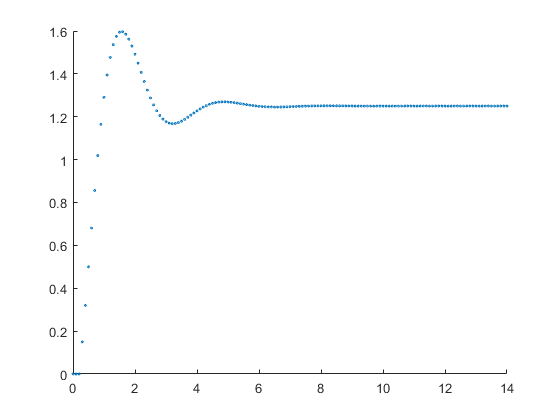

t  = 0:dt:14;   % time vektore
u = ones(size(t)); u(1) = 0;    % step input
du(1) = 0;  % initial value 0 and time 
y(1) = 0; 
dy(1) = 0; 
ddy(1) = 0;
for i = 2:length(t);    % controller loop
    du(i) = (u(i)-u(i-1)) / dt;
    dy(i) = dy(i-1) + dt*ddy(i-1);
     y(i) = y(i-1) + dt*dy(i-1);
   ddy(i) = du(i) + 5*u(i) -2*dy(i) -4*y(i);   
end
scatter(t,y,3)  % scatter plot

**State space**

dt = 0.1    % sample time

dt = 0.1000

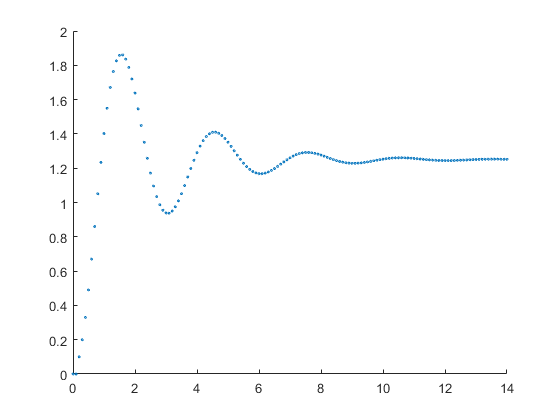

t  = 0:dt:14;   % time vektore
u = ones(size(t)); u(1) = 0;    % step input
A = [-2, -2;
      2,  0];
B = [2;
     0];
C = [0.5, 1.25];
D = 0;
x(:,1) = [0;0]; % initial value 0 and time 
dx(:,1) = [0;0];

for i = 2:length(t);    % controller loop
    x(:,i) = x(:,i-1) +dt*dx(:,i-1); 
    dx(:,i) = A*x(:,i-1) + B*u(i);
    y(i) = C*x(:,i) + D*u(i);
end
scatter(t,y,3)  % scatter plot